# **IO3xx SSI - Loopback **

This example demonstrates the use of the SSI Slave, Master and Sniffer driver blocks. The model is set up in a loop back configuration. The SSI Master reads data from the SSI Slave encoder connected via loopback wiring on the terminal board. The SSI Sniffer is connected in parallel and decodes the communication.

## Setup

### Prerequisites

The following elements are required to run this example:

- Speedgoat real-time target machine with one configurable I/O module from the IO3xx family

- Speedgoat configuration file that supports **1x SSI Master, 1x SSI Slave and 1x SSI Sniffer channel.**  

- Connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

### Test Setup

In this example, the SSI Slave sends data to the SSI Master and the SSI Sniffer monitors the communication.You must therefore connect the corresponding pins on the terminal board as indicated in the following pin wiring table. The exact pins depend on your specific configuration file (bitstream). 

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires.

If your configuration file doesn't include an SSI Sniffer code module, you can comment out the corresponding block in the Simulink Real-Time model.

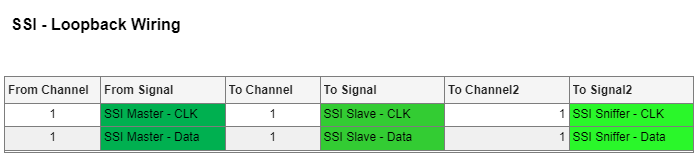

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_SSI_Loopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

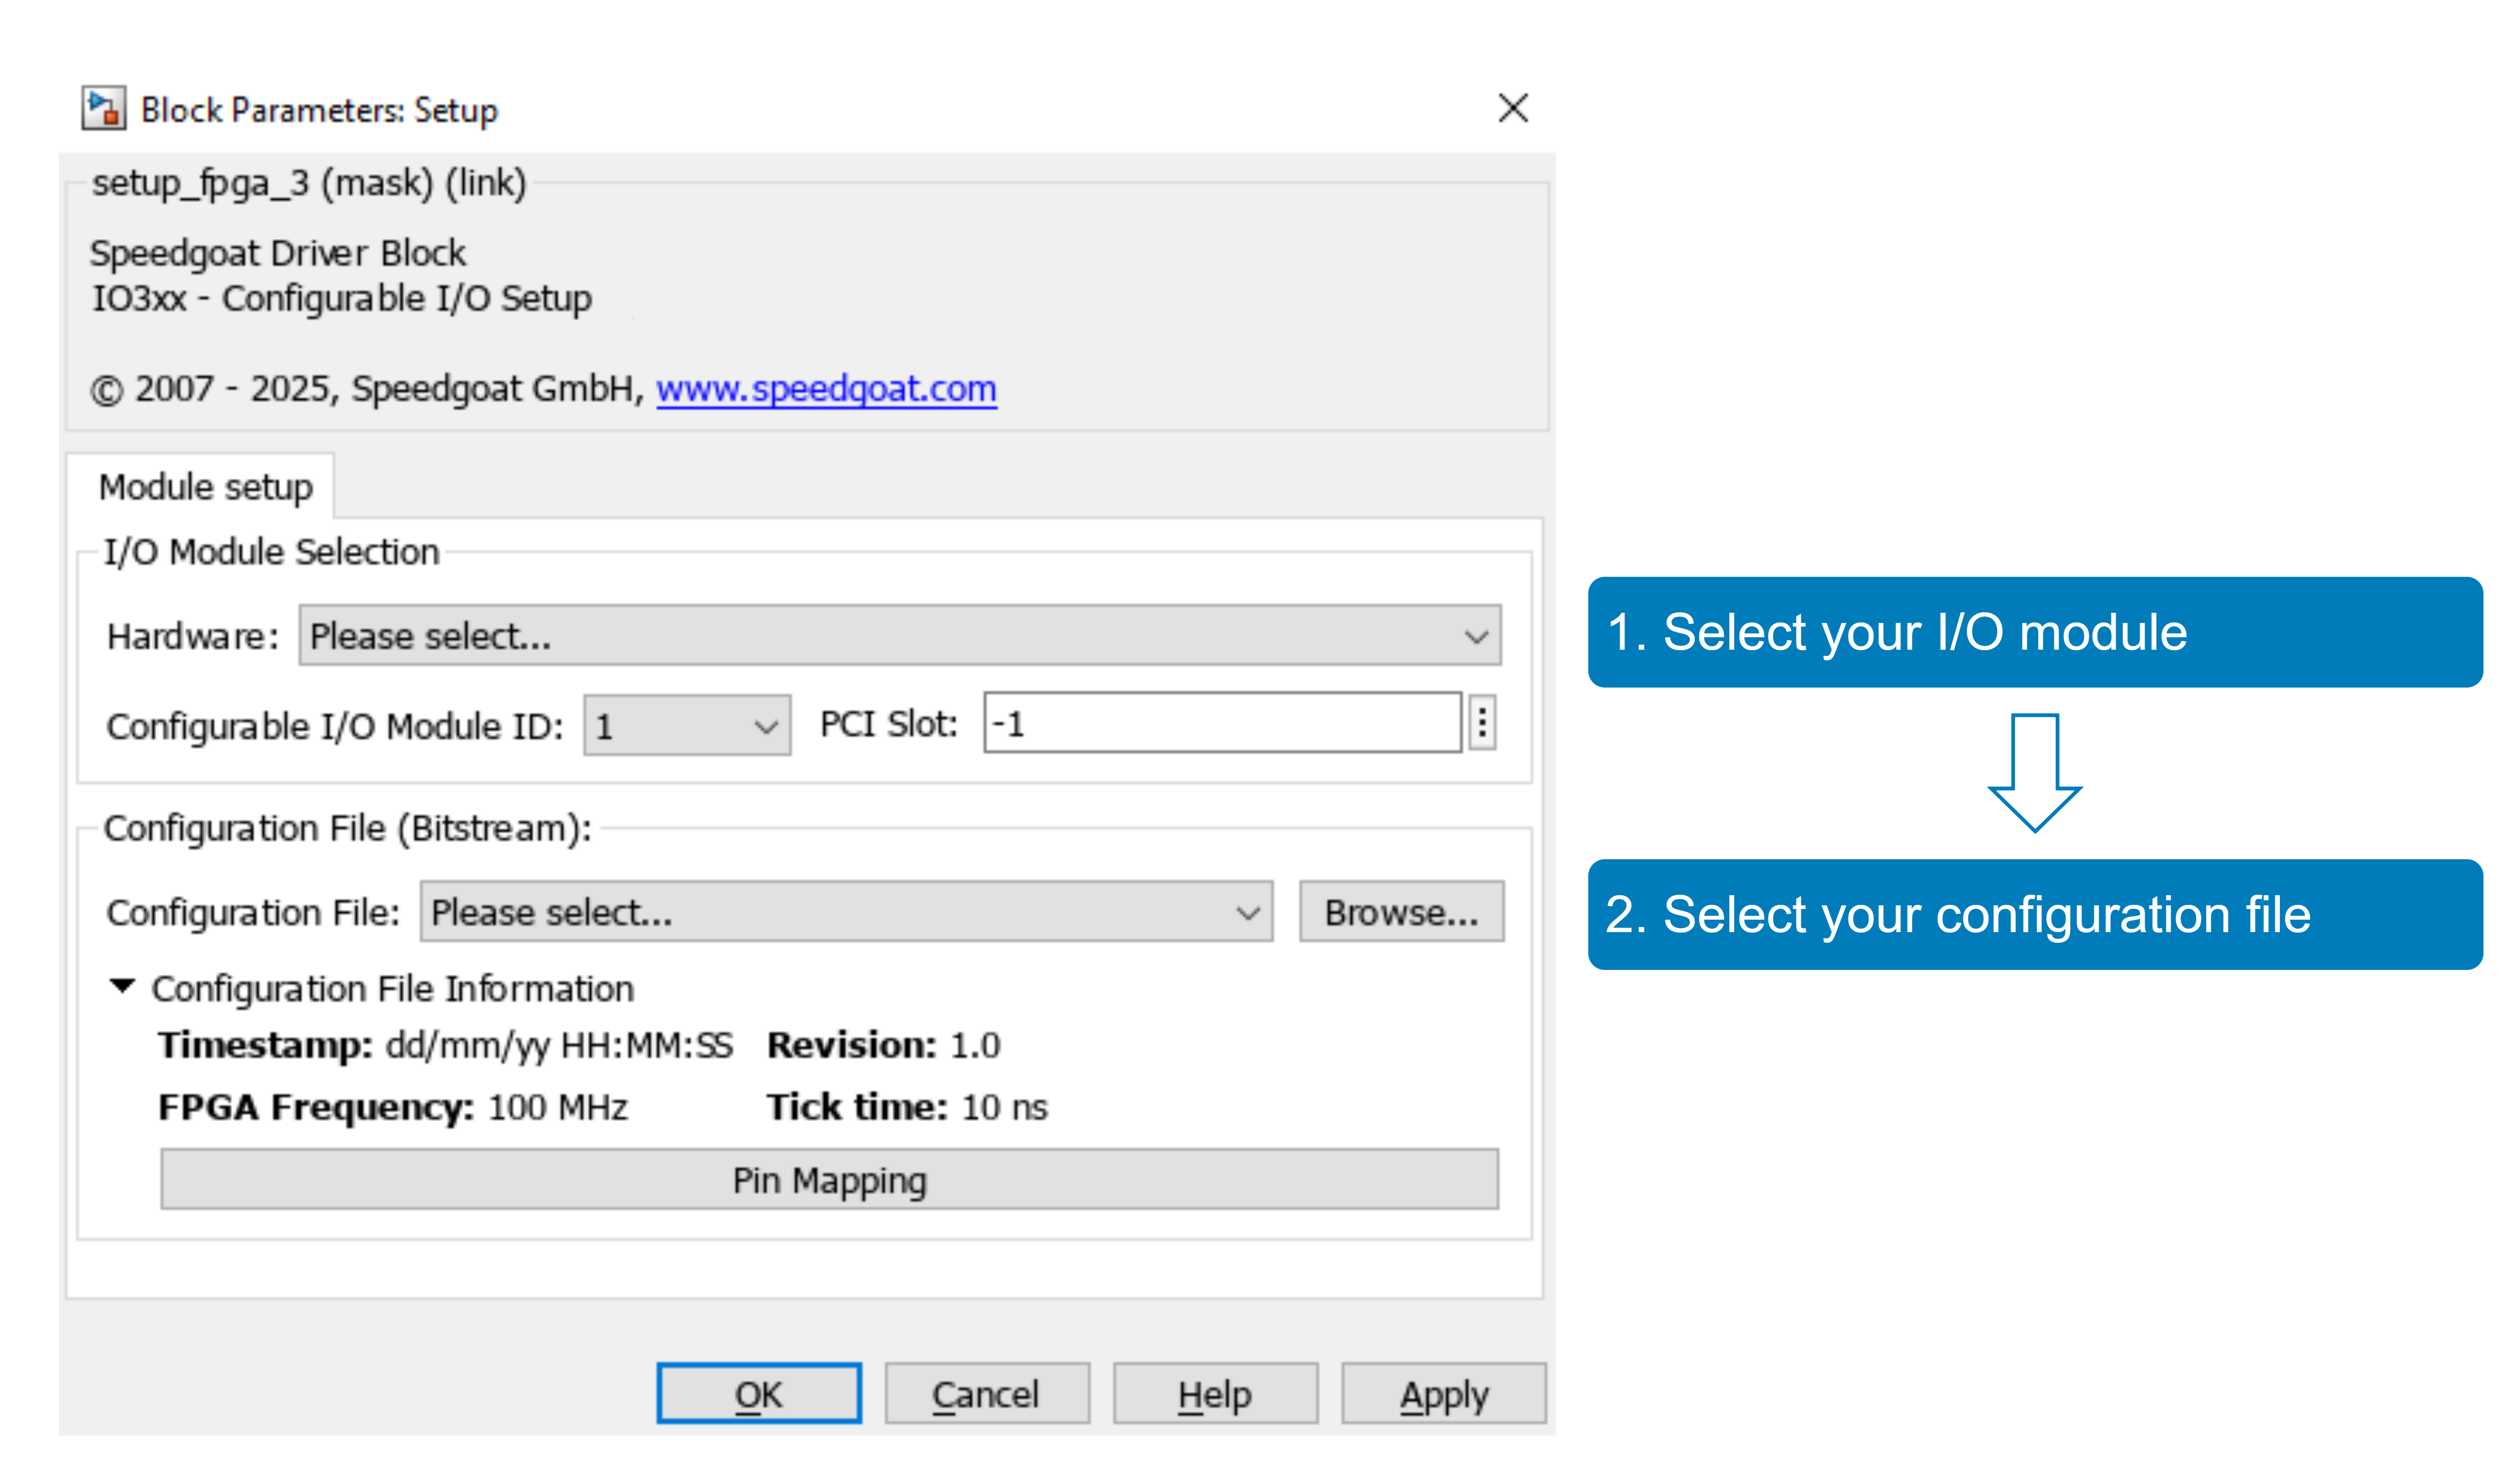

With the **Pin Mapping** button you can now check where the functionalities are located.

## Model Description 

The model contains an instance of the SSI Master block, one SSI Slave block and an instance of the SSI Sniffer block. Both instances use channel 1 (**Channel Vector** parameter). The values of a 8-bit counter are transmitted by the SSI Slave module and received with the SSI Master block with an SSI-Clock Frequency of 1MHz. The SSI Sniffer intercepts and decodes the communication.

The timing diagramm below illustrates the SSI protocol:

The SSI Master is driving the clock line with a frequency of 1MHz (T = 1us). This value is set in the SSIM mask, and depending upon the used Configuration File and the corresponding FPGA-Frequency set to the nearest achievable frequency. The nearest achievable Frequency is displayed in the **SSI-Master block** next to the **Frequency** field.

The idle time between two SSI messages (TP) is set to 11 us. Transfer time-out is set to 5us which is the time the slave will hold the data line low and release it high after Tm to signal the end of the message.

To avoid synchronicity issues, the master is set to "Synchronization waiting time applicable" mode. The SSI-Slave block has the highest priority, the master block the second highest and the sniffer block the lowest priority. At every simulation step, the following sequence applies:

- The slave sets new data that will be available in the next SSI frame

- The master triggers a SSI Frame, waits until it's finished and reads the data from the same sample step

- The sniffer reads the data from the same sample step

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode  

% Start the real-time application
tg.setStopTime(10);
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

Open the Simulink scopes in the model to verify that the loopback is wired correctly. 

- The SSI Master scope must display the 8-bit counter sent by the SSI Slave module.

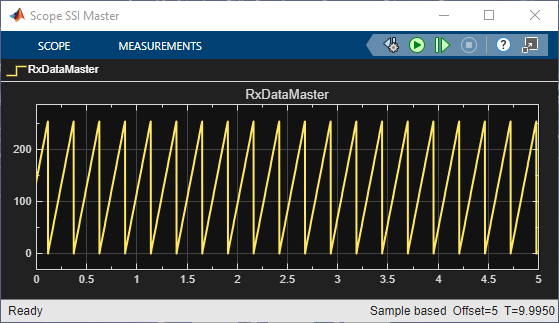

- The SSI Sniffer scope will display the following 3 subplots:

- The 8-bit counter values detected on the Rx Data line

- The measured clock frequency (must be 1e6 [Hz], resp at the nearest achievable frequency depending upon the configuration file)

- A: The Number of Bits detected (must be 8) / B: Erounes amount of bits detected (must be 0) / C: SSI2 detection (must be 1)

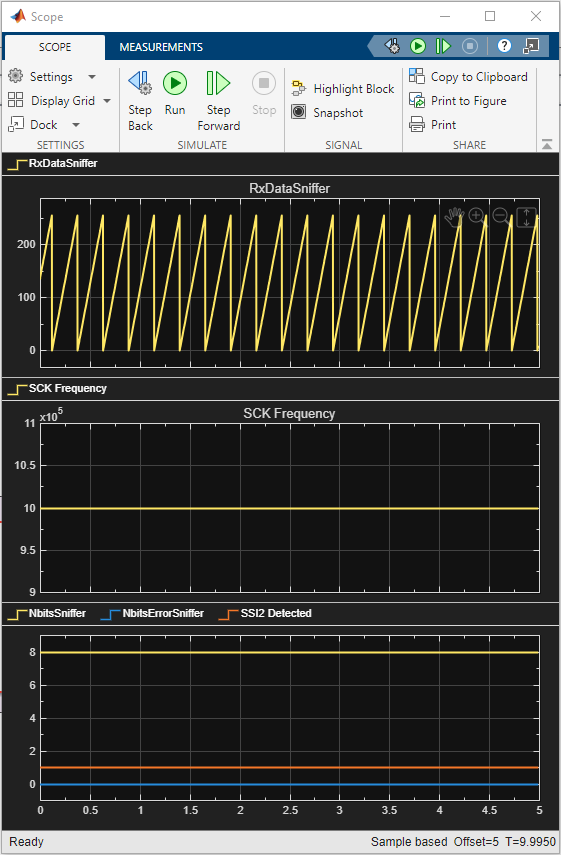

## Additional References

- [SSI documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_ssi)